## Data

male = [
    155.2; 158.7; 159.2; 162.1; 163.2;
    164.3; 164.6; 165.9; 167.2; 167.5;
    168.3; 170.5; 172.6; 177.5; 179.7
];

female = [
    150.1; 152.9; 153.4; 153.9; 154.2;
    156.6; 158.0; 158.1; 158.3; 158.6;
    159.8; 160.2; 161.1; 161.4
];

male = sort(male);
female = sort(female);

Mean and variance of male and female

mean_male = mean(male)

mean_male = 166.4333

std_male = std(male)

std_male = 6.7294

var_male = var(male)

var_male = 45.2852


mean_female = mean(female)

mean_female = 156.9000

std_female = std(female)

std_female = 3.4592

var_female = var(female)

var_female = 11.9662


n_male = length(male)

n_male = 15

n_female = length(female)

n_female = 14

**Q 1.1  **

a = 0.05;
zval = 1.96;
chi_0975 = 13.844;
chi_0025 = 41.923;

[
    n_female * var_female / chi_0025;
    n_female * var_female / chi_0975;
]

ans =     3.9960
   12.1010


we can find the z-value for 95% confidence level is 1.96, $\chi_{0.975}^2=13.844, \chi_{0.025}^2 = 41.923$, hence the 95% confidence interval for the variance of female is

$\left[\frac{(n-1)s^2}{\chi_{0.025^2}},\frac{(n-1)s^2}{\chi_{0.975^2}}\right]$i.e. $[3.996, 12.101]$.

**Q 1.2**

ta = 1.771;
low = mean_female - std_female / sqrt(n_female) * ta

low = 155.2627

We can find the $t$ value for 95% confidence level is 1.771, hence the 95% lower one-side confidence interval for the mean of female's population is 


$$\bar{x} - \frac{t_\alpha s}{\sqrt{n}} = 155.26$$


** Q 1.3**

[p, h] = signrank(female, 154, 0.05)

p = 0.0134

h = logical
   1


$h=1$, which means that at 95%, the null hypothesis can be rejected.

**Q 1.4**

vartest2([male;female], [ones(n_male, 1); 2 * ones(n_female, 1)], 'Alpha', 0.10)

ans = 1

The answer is 1, hence the assuption is rejected,

**Q 1.5**

[H, P, CI, STATS] = ttest2(male, female, "Alpha", 0.1, "Tail", 'right')

H = 1

P = 3.0301e-05

CI =     6.8934
       Inf


STATS = struct with fields:
    tstat: 4.7440
       df: 27
       sd: 5.4077


since $h=1$, hence the assumption is rejected.

**Q 1.6**

s = 2 * normcdf(-abs(mean_male - mean_female), 0, min(std_male, std_female))

s = 0.0059

Hence the confidence interval of difference of heights is $[5.41, 13.66]$.

**Q 1.7**

[p, h, stats] = ranksum(male, female, 0.05)

p = 1.3410e-04

h = logical
   1


stats = struct with fields:
       zval: 3.8188
    ranksum: 313


since $h=1$, male and female populations don't have the same median under 5% significant level.

## Q2

**Q 2.1**

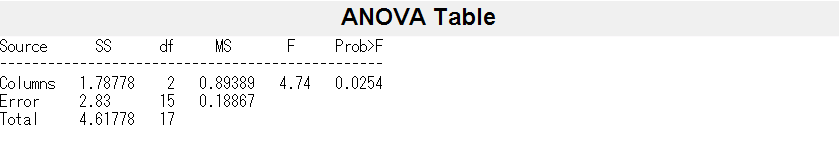

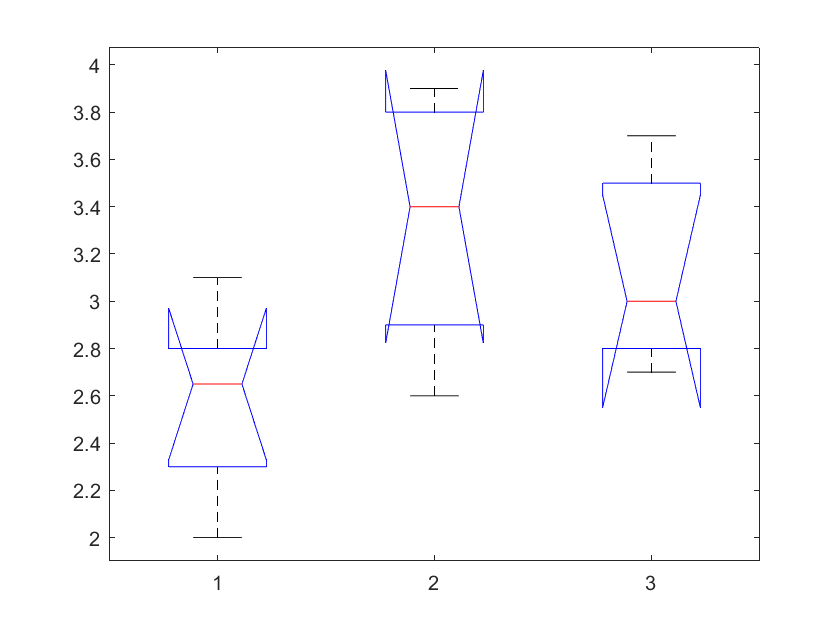

p = 0.0254

stats = struct with fields:
    gnames: [3×1 char]
         n: [6 6 6]
    source: 'anova1'
     means: [2.5833 3.3333 3.1167]
        df: 15
         s: 0.4344


xs = [2.0 2.3 2.7 2.6 2.8 3.1;
    2.6 2.9 3.3 3.5 3.8 3.9;
    2.7 3.0 3.7 2.8 3.0 3.5];
xs = xs';

[p, ~, stats] = anova1(xs)

**Q 2.2**

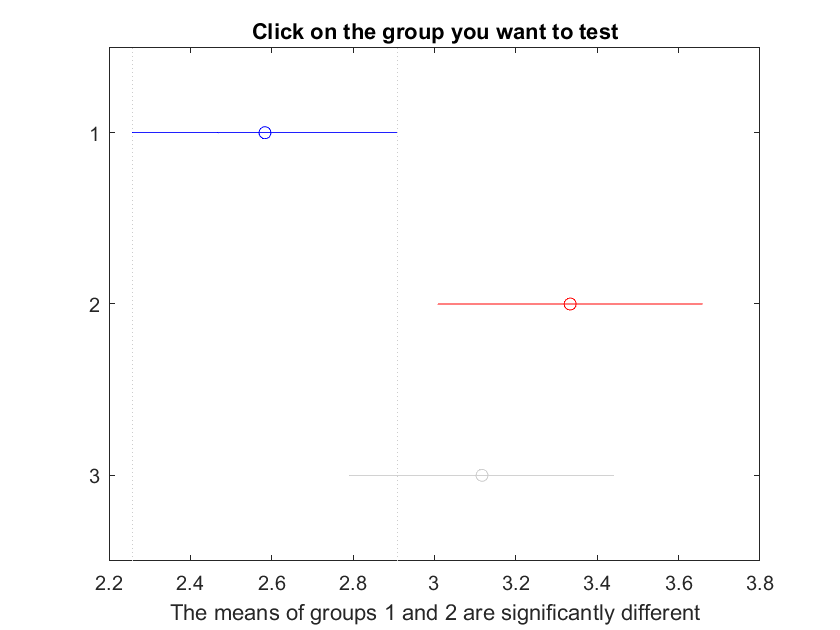

[results, means, ~, gnames] = ...
    multcompare(stats, "Alpha", 0.05);

## Q3

expenses = [1.217 1.252 0.857 1.022 0.816 0.951 0.934 0.703 0.968 0.655 0.802 1.125 0.752 0.692 0.725 0.642 0.683 0.527 0.553 0.690];
incomes = [16.0 15.8 11.5 13.4 10.0 11.7 11.8 9.0 16.3 8.2 10.3 16.9 9.8 8.4 9.6 7.9 8.4 7.4 6.7 8.5];

**Q 3.1** scatter figure

figure
scatter(incomes, expenses)
xlabel("Incomes")
ylabel("Expenses")

**Q 3.2 **

y = expenses';
x = incomes';

A = [ones(length(y), 1) x];
cs = A \ y

cs =     0.1575
    0.0617


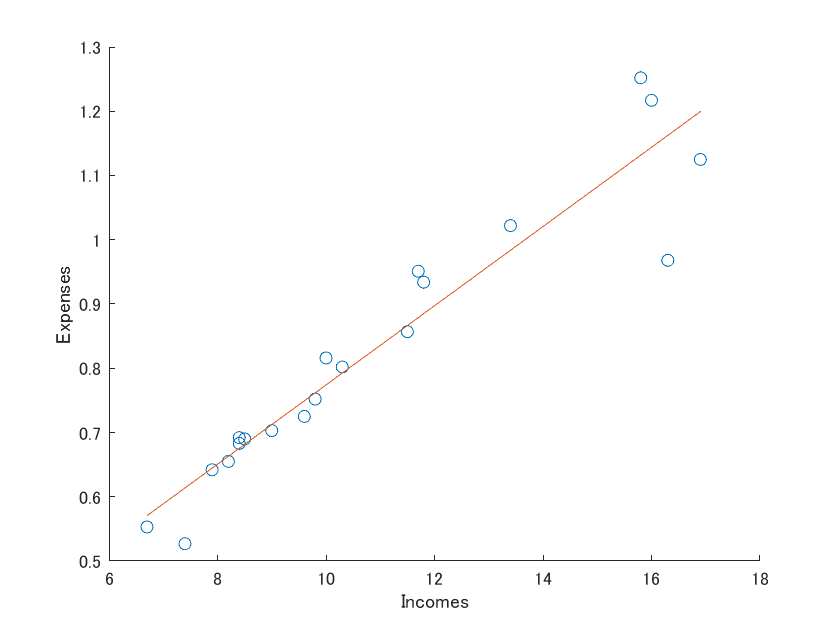

yhat = cs(1) + cs(2) * x;

hold on
plot(x, yhat);
hold off


fitres = fit(x, y, 'poly1')

fitres =      線形モデル Poly1:
     fitres(x) = p1*x + p2
     係数 (95% の信頼限界):
       p1 =     0.06166  (0.05143, 0.07188)
       p2 =      0.1575  (0.04175, 0.2732)

ci = confint(fitres, 0.95)

ci =     0.0514    0.0417
    0.0719    0.2732


Hence the regression line is $y=0.06166x + 0.1575$, with 95% two-sided confidence intervals for $\beta_0$ is $[0.0417, 0.2732]$ for $\beta_1$ is $[0.0514, 0.0719]$.

Rs = 1 - sum((y - yhat) .^ 2) / sum((y - mean(y)) .^ 2)

Rs = 0.8992

$R^2=0.8992$, which is high, hence there is a strong correlation between incomes and expenses.

**Q 3.3**

cl = y - polyval([fitres.p1, fitres.p2], x)

cl =     0.0730
    0.1204
   -0.0095
    0.0383
    0.0420
    0.0721
    0.0490
   -0.0094
   -0.1945
   -0.0081



[h1, sig, ci] = ttest(cl, 0, 0.05)

h1 = 0

sig = 1.0000

ci =    -0.0310
    0.0310


[h2, P, Jbtest, CV] = lillietest(cl, 0.05)

h2 = 1

P = 0.0252

Jbtest = 0.2063

CV = 0.1920

T test accepts that the residual is normally distrubuted while lillietest rejects it.

**Q 3.4/3.5**

X = 10.5;
Y = cs(1) + cs(2) * X

Y = 0.8049


[p, S] = polyfit(x, y, 1)

p =     0.0617    0.1575


S = フィールドをもつ struct :
        R: [2×2 double]
       df: 18
    normr: 0.2886


[yfit, delta] = polyconf(p, [X], S, 'alpha', 0.05)

yfit = 0.8049

delta = 0.1465


[Y - delta, Y + delta]

ans =     0.6584    0.9514


Hence the mean value of $Y$ is $0.8049$, and the 95% confidence interval for Y at $x=10.5$ is $[0.6584, 0.9514]$.